# BBC Ensmeble Training

clear;
close all;
bdclose('all');
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/BBC/model')
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/BBC/DRL_training')
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/BBC/DRL_training/trained_agent')
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/BBC/abstraction/')

% addpath('/Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/model')
% addpath('/Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/DRL_training/trained_agent')
% addpath('/Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/abstraction/')

## Environment Setup

kinova_params;
numObs = 22;            % Number of observations
numAct = 2;             % Number of actions
Ts = 0.01;
Tf = 3;
Ts_sample = Ts;

isEval = false;         % random input generation
isTerminate = true;     % no terminatin during simulation

## Load Constitutional Controllers

myFolder = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/BBC/DRL_training/trained_agent";
% myFolder = "/Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/DRL_training/trained_agent";

% check if folder path is valid
if ~isfolder(myFolder)
    errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
    uiwait(warndlg(errorMessage));
    return;
end

% load all .MAT files under determined folder
filePattern = fullfile(myFolder, '*.mat');
matFiles = dir(filePattern);
[fileNumber, ~]= size(matFiles);

% get selected DRL agents
matFiles = struct2cell(matFiles);
allAgentName = matFiles(1,:);
allAgentName = convertCharsToStrings(allAgentName)';
allAgentName = [allAgentName(1);allAgentName(4:5);allAgentName(7:end)];

% load trained RL controllers
rlAgentName = allAgentName;

agent1 = load(rlAgentName(1)).saveAgent.agent;
agent2 = load(rlAgentName(2)).saveAgent.agent;
agent3 = load(rlAgentName(3)).saveAgent.agent;
agent4 = load(rlAgentName(4)).saveAgent.agent;
agent5 = load(rlAgentName(5)).saveAgent.agent;
agent6 = load(rlAgentName(6)).saveAgent.agent;
agent7 = load(rlAgentName(7)).saveAgent.agent;
agent8 = load(rlAgentName(8)).saveAgent.agent;
agent9 = load(rlAgentName(9)).saveAgent.agent;

numRL = 9;                          % num of RL controllers
predIndexVector = 3;                % only take the total reward as the prediction result

% load abstracted MDP
abstractMDP = load("BBC_abstract_model").abModel;
actionUB1 = abstractMDP.actionUB_1;
actionUB2 = abstractMDP.actionUB_2;
rewardUB1 = abstractMDP.rewardUB_1;
rewardUB2 = abstractMDP.rewardUB_2;
actionToIndex = abstractMDP.actionToIndexTable;
rewardToIndex = abstractMDP.rewardToIndexTable;
tranTable = abstractMDP.tranTable;
stateTable = tranTable(:,1);
actionTable = tranTable(:,2);

## DRL Obs/Act configuration

Creating an environment model includes action, obervation

**Observation**: 

- +22 original obs

- +9 Predictions

**Action**: Fuel injected, [0.13, 1.66]

% if use prediction as additional features
isPred = true;

if isPred
% observation
    obsInfo = rlNumericSpec([numObs+9 1],...
        'LowerLimit', -inf*ones(numObs+9,1),...
        'UpperLimit', inf*ones(numObs+9,1));
    obIsnfo.Name = 'observations';
    obsInfo.Description = 'state, predicted semantics';
    numObservations = obsInfo.Dimension(1);
else
    obsInfo = rlNumericSpec([numObs 1],...
        'LowerLimit', -inf*ones(numObs,1),...
        'UpperLimit', inf*ones(numObs,1));
    obIsnfo.Name = 'observations';
    obsInfo.Description = 'state';
    numObservations = obsInfo.Dimension(1);
end

% action
actInfo = rlFiniteSetSpec([1 2 3 4 5 6 7 8 9]);
actInfo.Name = 'controller selection';
numActions = actInfo.Dimension(1);

mdl = 'BBC_ensemble_training';
agentblk = [mdl, '/Ensemble Control System/ensemble_RL'];

% Build the environment interface object.
env = rlSimulinkEnv(mdl,agentblk,obsInfo,actInfo);

env.ResetFcn = @kinovaResetFcn;

## DRL Agent Configuration

Create a network to be used as underlying critic approximator

criticNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(128,'Name','CriticStateFC2')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(256,'Name','CriticCommonFC1')
    reluLayer('Name','CriticCommonRelu2')
    fullyConnectedLayer(128,'Name','CriticCommonFC2')
    reluLayer('Name','CriticCommonRelu3')
    fullyConnectedLayer(64,'Name','CriticCommonFC3')
    reluLayer('Name','CriticCommonRelu4')
    fullyConnectedLayer(1,'Name','CriticOutput')];

% convert the network to a dlnetwork object
criticNetwork = dlnetwork(criticNetwork);

% create critic based on the network approximator
critic = rlValueFunction(criticNetwork,obsInfo,'UseDevice','cpu');

% create a network to be used as underlying actor approximator
actorNetwork = [
    featureInputLayer(prod(obsInfo.Dimension),'Normalization','none','Name','observation')
    fullyConnectedLayer(32,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(64,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(128,'Name','ActorFC3')
    reluLayer('Name','ActorRelu3')
    fullyConnectedLayer(64,'Name','ActorFC4')
    reluLayer('Name','ActorRelu4')
    fullyConnectedLayer(length(actInfo.Elements),'Name','ActorFC5')                       
    softmaxLayer('Name','actionProb')];

actor  = rlDiscreteCategoricalActor(actorNetwork,obsInfo,actInfo);

% Optimization options for actors and critics
myCriticOpts=rlOptimizerOptions(...
    'LearnRate',2e-3,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-3,...
    'Optimizer',"adam");

myActorOpts=rlOptimizerOptions(...
    'LearnRate',1e-3,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-3,...
    'Optimizer',"adam");

agentOptions = rlACAgentOptions(...
    'CriticOptimizerOptions', myCriticOpts,...
    'ActorOptimizerOptions',myActorOpts,...
    'SampleTime',Ts,...
    'NumStepsToLookAhead',5,...
    'EntropyLossWeight',0.01,...
    'DiscountFactor',0.99);

% agent creation
agentEnsemble = rlACAgent(actor, critic, agentOptions);

## **Training Configurations**

Change the weights distribution among subsitutional rewards

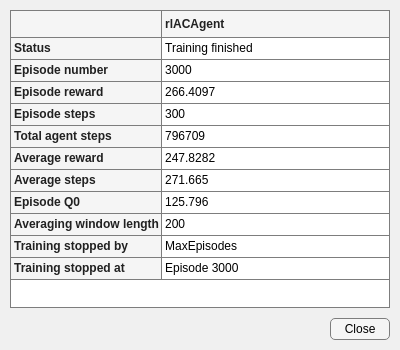

maxepisodes = 3000; 
window_length = 200;
plateWeight = 0.1;
ballWeight = 1;
stableWeight = 0.05;
rewardWeights = [plateWeight, ballWeight, stableWeight];

ensemblePlateWeight = 0.2;
ensembleBallWeight = 1.5;
ensembleStableWeight = 0.05;
ensembleRewardWeights = [ensemblePlateWeight, ensembleBallWeight, ensembleStableWeight];
maxsteps = floor(Tf/Ts);

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', maxepisodes, ...
    'MaxStepsPerEpisode', maxsteps, ...
    'ScoreAveragingWindowLength',window_length, ...
    'StopTrainingCriteria','AverageSteps',...
    'StopTrainingValue', maxsteps*0.95,...
    'Verbose', false,...
    'Plots','training-progress',...
    'UseParallel',false);

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agentEnsemble,env,trainOpts);
else
%     agent = load('preTrainedAgent.mat');
%     agent = agent.agent;
end

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = false;

if isSave
    dateOfTrain = date;
    if isPred
        agentName = ['BBC-ensemble-pred-AC-new-9-RL-0-PID-', dateOfTrain(1:end-5)];
    else
        agentName = ['BBC-ensemble-no-pred--AC-9-RL-0-PID-', dateOfTrain(1:end-5)];
    end
    agentName = agentName+...
        "-"+string(ensembleRewardWeights(1))+...
        "-"+string(ensembleRewardWeights(2))+...
        "-"+string(ensembleRewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agentEnsemble, ...
                 'rewardWeights', ensembleRewardWeights, ...
                 'ensembleMPC',[],...
                 'agentOptions', agentOptions, ...
                 'criticNetwork', criticNetwork, ...
                 'actorNetwork', actorNetwork, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/BBC/ensemble/trained_agent/";
    save(path+agentName+'.mat', "saveAgent");
    disp(agentName + ' saved')
end

BBC-ensemble-pred-AC-new-9-RL-0-PID-28-Jul-0.2-1.5-0.05 saved


## Simulation & Plotting

maxsteps = Tf/Ts;
simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');

% get results
[ball,R6_q0,R7_q0,U0] = BBC_ResetFun();
experiences = sim(env,agentEnsemble,simOpts);

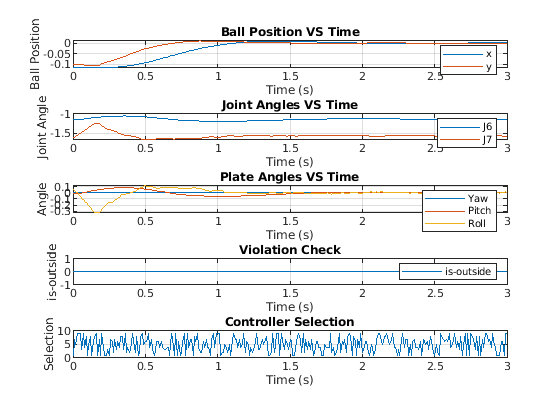

 
% state
x_ball = experiences.SimulationInfo.logsout.getElement('x_ball').Values.Data;
y_ball =  experiences.SimulationInfo.logsout.getElement('y_ball').Values.Data;
plate_yaw =  experiences.SimulationInfo.logsout.getElement('plate_yaw').Values.Data;
plate_pitch =  experiences.SimulationInfo.logsout.getElement('plate_pitch').Values.Data;
plate_roll =  experiences.SimulationInfo.logsout.getElement('plate_roll').Values.Data;
theta_J6 =  experiences.SimulationInfo.logsout.getElement('theta_J6').Values.Data;
theta_J7 =  experiences.SimulationInfo.logsout.getElement('theta_J7').Values.Data;
is_outside =  experiences.SimulationInfo.logsout.getElement('is_outside').Values.Data;
% action
torque_J6 =  experiences.SimulationInfo.logsout.getElement('torque_J6').Values.Data;
torque_J7 =  experiences.SimulationInfo.logsout.getElement('torque_J7').Values.Data;
% reward
plate_reward =  experiences.SimulationInfo.logsout.getElement('plate_reward').Values.Data;
ball_reward =  experiences.SimulationInfo.logsout.getElement('ball_reward').Values.Data;
stable_reward =  experiences.SimulationInfo.logsout.getElement('stable_reward').Values.Data;
final_reward =  experiences.SimulationInfo.logsout.getElement('final_reward').Values.Data;
selection =  experiences.SimulationInfo.logsout.getElement('selection').Values.Data;


steps = length(x_ball);
time = 0:Ts_sample:(steps-1)*Ts_sample;


% plotting
figure(1);
subplot(5,1,1)
plot(time,x_ball, time,y_ball);
title('Ball Position VS Time');
legend('x', 'y');
xlabel('Time (s)');
ylabel('Ball Position');
grid on;

subplot(5,1,2)
plot(time,theta_J6, time,theta_J7);
title('Joint Angles VS Time');
legend('J6', 'J7');
xlabel('Time (s)');
ylabel('Joint Angle');
grid on;

subplot(5,1,3)
plot(time,plate_yaw, time,plate_pitch, time,plate_roll);
title('Plate Angles VS Time');
legend('Yaw', 'Pitch', 'Roll');
xlabel('Time (s)');
ylabel('Angle');
grid on;

subplot(5,1,4)
plot(time,is_outside);
title('Violation Check');
legend('is-outside');
xlabel('Time (s)');
ylabel('is-outside');
grid on;

subplot(5,1,5)
plot(time,selection);
title('Controller Selection');
xlabel('Time (s)');
ylabel('Selection');
grid on;

## Training progress info

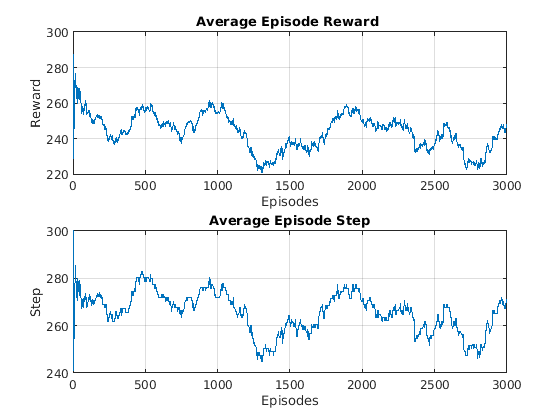

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(3);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on

## Environment Reset Function

function in = kinovaResetFcn(in)
    % Ball parameters
    ball.radius = 0.02;     % m
    ball.mass   = 0.0027;   % kg
    ball.shell  = 0.0002;   % m
    
    % Calculate ball moment of inertia.
    ball.moi = calcMOI(ball.radius,ball.shell,ball.mass);
    
    % Initial conditions. +z is vertically upward.
    % Randomize the x and y distances within the plate.
    ball.x0  = -0.125 + 0.25*rand;  % m, initial x distance from plate center
    ball.y0  = -0.125 + 0.25*rand;  % m, initial y distance from plate center
    ball.z0  = ball.radius;         % m, initial z height from plate surface
    
    ball.dx0 = 0;   % m/s, ball initial x velocity
    ball.dy0 = 0;   % m/s, ball initial y velocity
    ball.dz0 = 0;   % m/s, ball initial z velocity
    
    % Contact friction parameters
    ball.staticfriction     = 0.5;
    ball.dynamicfriction    = 0.3; 
    ball.criticalvelocity   = 1e-3;
    
    % Convert coefficient of restitution to spring-damper parameters.
    coeff_restitution = 0.89;
    [k, c, w] = cor2SpringDamperParams(coeff_restitution,ball.mass);
    ball.stiffness = k;
    ball.damping = c;
    ball.transitionwidth = w;
    
    in = setVariable(in,"ball",ball);
    
    % Randomize joint angles within a range of +/- 5 deg from the 
    % starting positions of the joints.
    R6_q0 = deg2rad(-65) + deg2rad(-5+10*rand);
    R7_q0 = deg2rad(-90) + deg2rad(-5+10*rand);
    in = setVariable(in,"R6_q0",R6_q0);
    in = setVariable(in,"R7_q0",R7_q0);
    
    % Compute approximate initial joint torques that hold the ball,
    % plate and arm at their initial congifuration
    g = 9.80665;
    wrist_torque_0 = ...
        (-1.882 + ball.x0 * ball.mass * g) * cos(deg2rad(-65) - R6_q0);
    hand_torque_0 = ...
        (0.0002349 - ball.y0 * ball.mass * g) * cos(deg2rad(-90) - R7_q0);
    U0 = [wrist_torque_0 hand_torque_0];
    in = setVariable(in,"U0",U0);

    % Animation
%     in = setPostSimFcn(in, @animatedPath);
end